clc;
clear;

## 基本数据

%潜油电泵设计基本数据

%静压(MPa)
P_r = 30.1600;
%目标产量(m^3/d)
Q_d = 440;
%原油API
API = 40;
%含水率
fw_1 = 0.6;
%井深(m)
h_j = 3500;
%井口压力要求(MPa)
P_jk = 1;
%每1000英尺油管长度内的压头损失
f_t_1000 = 10;


%有杆泵举升设计基本参数
%油藏中深
H_oil = 1690;
%油藏压力(MPa)
P_oil = 16.9;
%油藏温度(摄氏度)
T_oil = 60;
%恒温层温度(摄氏度)
T_all = 16;
%恒温层深度(m)
h_all = 20;
%套管内径(m)
d_in = 0.124;
%地面脱气油粘度(mPa·s)
mu_oil = 30;
%油相对密度
gamma_oil = 0.85;
%气相对密度
gamma_gas = 0.75;
%地层水相对密度
gamma_water = 1.0;
%泡点压力(MPa)
P_p = 10;
%套压(MPa)
P_t = 0;
%油压(MPa)
p_oil = 0.5;
%生产气油比
A_gas_oil = 40;
%井口产出液体积含水率
W_jk = 0.3;
%测试点产液量(m^3/d)
Q_test = 20;
%测试点井底流压(MPa)
P_test = 5;
%配产液量(m^3/d)
Q_need = 15;

## 潜油电泵设计

%确定吸入口压力
PI = 69.16;

%目标产量下的井底流压(MPa)


$$$$P_{w f d}=P_{r}-\left(\frac{Q_{d}}{P I}\right)$$$$


P_wfd = P_r-(Q_d/PI)

P_wfd = 23.7979

%计算原油密度
mu_oil_API_40 = (141.5/(API+131.5))*1000

mu_oil_API_40 = 825.0729

%计算液柱压力
mu_a = mu_oil_API_40*(1-fw_1)+1000*fw_1

mu_a = 930.0292

P_mix = (mu_a*9.8*h_j)/(10^6)

P_mix = 31.9000

%计算泵入口压力
P_pump =  P_wfd - P_mix

P_pump = -8.1021

%设计下泵深度(m)
b_h = 3000;

%计算相对密度
SG_L = 1*fw_1+(mu_oil_API_40/1000)*(1-fw_1)

SG_L = 0.9300

%吸入口压力


$$$$P_{l}=P_{w f d}-\left[\frac{(数据点深度-泵挂深)\times S G_{l}}{2.31ft./ psi}\right]$$$$


P_I = P_wfd - ((h_j-b_h)*SG_L)/100

P_I = 19.1478

%确定总动压头(m)
H_js = h_j -(P_wfd*100)/SG_L

H_js = 941.1618

油管选择：3 1/2英寸（88.9 mm）

%计算油管摩阻损失
F_t = f_t_1000*(b_h/1000)

F_t = 30

%井口压力要求转换成水压头


$$$$\text{ Head}(f t)=\frac{p s i\times 2.31 f t./ p s i}{S G_{L}}$$$$


Head_ft = (P_jk*100)/SG_L

Head_ft = 107.5235

%总动压头
H = F_t + Head_ft + H_js

H = 1.0787e+03

生产层套管：外径为7英寸(177.8 mm)

440立方米/天 = 2767.5765326115493 bbl/d

泵型：538P31

%确定泵型

%请输入泵的单级扬程（m）
Delta_h = 20;

%泵的级数
n = H/Delta_h

n = 53.9343


%离心泵功率(kw)

%请输入单机功率
BHP_1 = 1.55

BHP_1 = 1.5500

N_over = BHP_1*n*SG_L

N_over = 77.7487


%请输入保护器功率(kw)
N_save = 1;

%总功率(BHP)
N = (N_save + N_over)*1.314

N = 103.4758

选择85.0112kw的高电压电机（2330V，30A）


%请输入电机的额定电压
U_dianji = 2330;
%请输入电机额定电流
I_dianji= 30;


%确定潜油电缆

%请输入潜油电缆作业温度(度)
Cable_temperature = 130;
%请输入该温度下电缆的放大系数
Amplification_factor  = 1.4326;
%请输入该电缆20摄氏度下每304.08米的压降（V）
Pressure_Drop_20 = 20;

选择6#号电缆

%变压器，变频控制器
%计算压力降
Delta_U = (Pressure_Drop_20*(b_h+50)*Amplification_factor)/304.8

Delta_U = 286.7080

%地面电压(v)
U_ground = U_dianji+Delta_U

U_ground = 2.6167e+03

%总的系统功率
KVA = (U_ground*I_dianji* sqrt(3))/1000

KVA = 135.9681

## 有杆泵举升设计

%确定下泵深度
q_t = 0:0.0001:30;
p_wf_all = predict_IPR_Petrobras(P_oil,P_test,P_p,Q_test,W_jk,q_t);

    0.7000

    1.7982

   12.4076

   22.3976



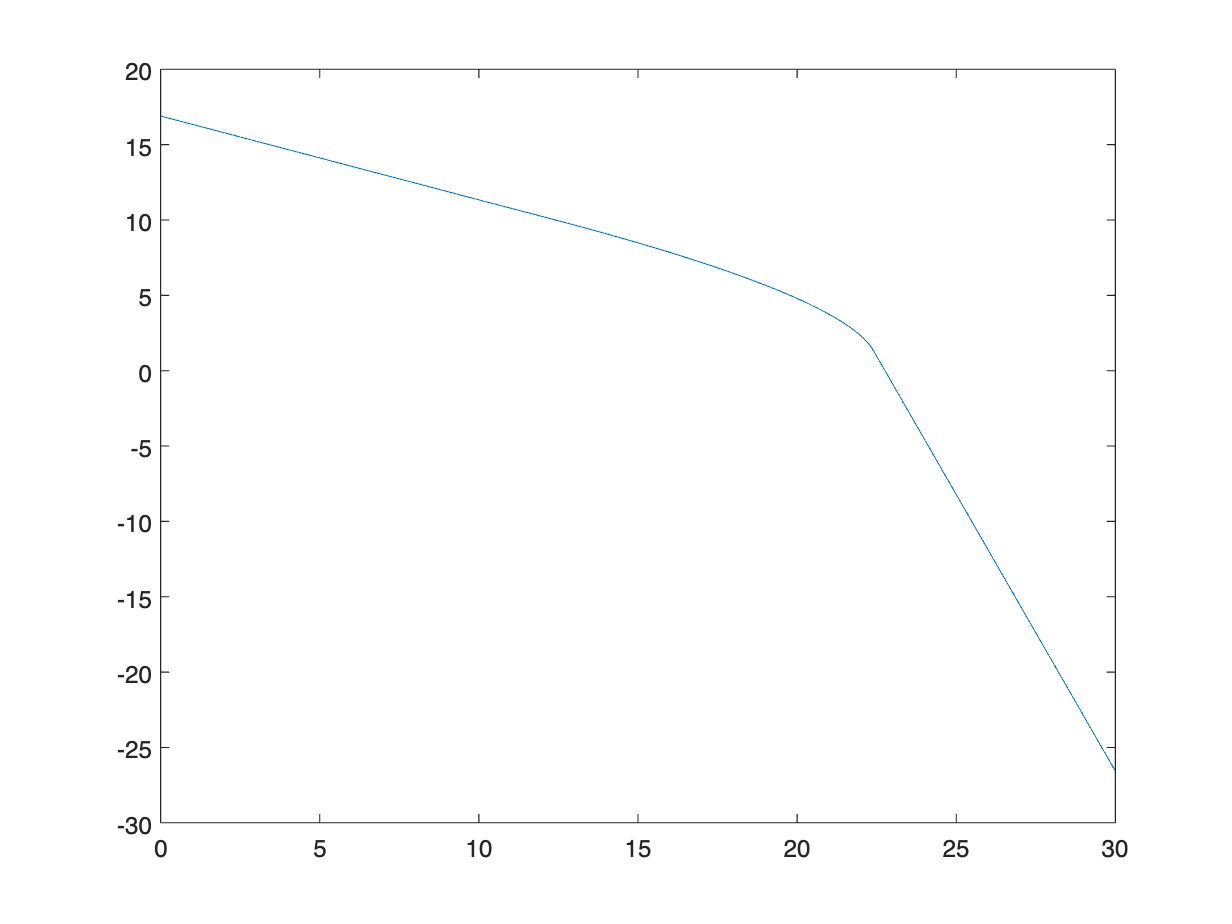

plot(q_t,p_wf_all)


% 使用线性插值获取对应的 p_wf
p_wf_target = interp1(q_t, p_wf_all, Q_need, 'linear');

% 显示结果
disp(['通过线性插值，当 q_t = ', num2str(Q_need), ' 时，p_wf = ', num2str(p_wf_target)]);

通过线性插值，当 q_t = 15 时，p_wf = 8.4838



%请输入下泵的深度
h_in = 1579.8;

%确定抽油机型号
%请输入抽油机型号
Oil_xinghao = "CYJ8-2.1-18";

%确定抽油机的冲次和泵径
%请输入抽油机的冲次
Oil_chongci = 8;
%请输入抽油机的冲程(m)
Oil_chongcheng = 2.1;
%请输入抽油泵泵径(m)
Oil_bengjin = 0.032;

%确定油管尺寸
%请输入油管外径(mm)
R_out = 73;
%请输入油管内径(mm)
R_in = 62;

%设计抽油杆柱组合
%请输入使用系数
A_use = 0.9;
%请输入抽油杆长度
L_youtube = h_in;
%从下往上一次输入每段直径(mm)-数组
e_e = [13,16];
%从下往上一次输入各段的比例-数组
l_e = [0.38,0.62];
L_e_l= l_e.*L_youtube

L_e_l =   600.3240  979.4760


%空气中每米抽油杆的重力
%上述直径对应的空气中每米抽油杆的重力-数组
qri = [10.22,15.48];
%请输入抽油杆分成几段
n_oil = 10;

L_Ji = (L_youtube/n_oil)*((1:1:n_oil))

L_Ji = 1.0e+03 *

    0.1580    0.3160    0.4739    0.6319    0.7899    0.9479    1.1059    1.2638    1.4218    1.5798


A_ri_n = (((e_e./1000).^2).*pi)./4

A_ri_n = 1.0e-03 *

    0.1327    0.2011


% 初始化一个存储索引的数组
Ari_J = zeros(1,n_oil)

Ari_J =      0     0     0     0     0     0     0     0     0     0


%空气中每米抽油杆的重力
Qri = zeros(1,n_oil)

Qri =      0     0     0     0     0     0     0     0     0     0



for i = 1:n_oil
    if L_Ji(i) - L_e_l(1) < 0
        Ari_J(i) = A_ri_n(1)
        Qri(i) = qri(1);
    elseif L_Ji(i) - L_e_l(1)>0 && abs(L_Ji(i) - L_e_l(1)) < (L_youtube/n_oil)*0.6
        Ari_J(i) = A_ri_n(1)
        Qri(i) = qri(1);
    else
        Ari_J(i) = A_ri_n(2)
        Qri(i) = qri(2);
    end
end

Ari_J = 1.0e-03 *

    0.1327         0         0         0         0         0         0         0         0         0


Ari_J = 1.0e-03 *

    0.1327    0.1327         0         0         0         0         0         0         0         0


Ari_J = 1.0e-03 *

    0.1327    0.1327    0.1327         0         0         0         0         0         0         0


Ari_J = 1.0e-03 *

    0.1327    0.1327    0.1327    0.1327         0         0         0         0         0         0


Ari_J = 1.0e-03 *

    0.1327    0.1327    0.1327    0.1327    0.2011         0         0         0         0         0


Ari_J = 1.0e-03 *

    0.1327    0.1327    0.1327    0.1327    0.2011    0.2011         0         0         0         0


Ari_J = 1.0e-03 *

    0.1327    0.1327    0.1327    0.1327    0.2011    0.2011    0.2011         0         0         0


Ari_J = 1.0e-03 *

    0.1327    0.1327    0.1327    0.1327    0.2011    0.2011    0.2011    0.2011         0         0


Ari_J = 1.0e-03 *

    0.1327    0.1327    0.1327    0.1327    0.2011    0.2011    0.2011    0.2011    0.2011         0


Ari_J = 1.0e-03 *

    0.1327    0.1327    0.1327    0.1327    0.2011    0.2011    0.2011    0.2011    0.2011    0.2011



%当前点以下抽油杆柱长度加权平均截面积
ArJ = zeros(1,n_oil)

ArJ =      0     0     0     0     0     0     0     0     0     0


disp(Ari_J)

   1.0e-03 *

    0.1327    0.1327    0.1327    0.1327    0.2011    0.2011    0.2011    0.2011    0.2011    0.2011



disp(Qri)

   10.2200   10.2200   10.2200   10.2200   15.4800   15.4800   15.4800   15.4800   15.4800   15.4800



L_A = (L_youtube/n_oil)./Ari_J

L_A = 1.0e+06 *

    1.1902    1.1902    1.1902    1.1902    0.7857    0.7857    0.7857    0.7857    0.7857    0.7857


for j = 1:n_oil
    ArJ(j) = ((L_youtube/n_oil)*j)/(sum(L_A(1:j)))
end

ArJ = 1.0e-03 *

    0.1327         0         0         0         0         0         0         0         0         0


ArJ = 1.0e-03 *

    0.1327    0.1327         0         0         0         0         0         0         0         0


ArJ = 1.0e-03 *

    0.1327    0.1327    0.1327         0         0         0         0         0         0         0


ArJ = 1.0e-03 *

    0.1327    0.1327    0.1327    0.1327         0         0         0         0         0         0


ArJ = 1.0e-03 *

    0.1327    0.1327    0.1327    0.1327    0.1424         0         0         0         0         0


ArJ = 1.0e-03 *

    0.1327    0.1327    0.1327    0.1327    0.1424    0.1497         0         0         0         0


ArJ = 1.0e-03 *

    0.1327    0.1327    0.1327    0.1327    0.1424    0.1497    0.1554         0         0         0


ArJ = 1.0e-03 *

    0.1327    0.1327    0.1327    0.1327    0.1424    0.1497    0.1554    0.1599         0         0


ArJ = 1.0e-03 *

    0.1327    0.1327    0.1327    0.1327    0.1424    0.1497    0.1554    0.1599    0.1636         0


ArJ = 1.0e-03 *

    0.1327    0.1327    0.1327    0.1327    0.1424    0.1497    0.1554    0.1599    0.1636    0.1667



Sucker_rod_string = struct();

Sucker_rod_string.LJ = L_Ji;
Sucker_rod_string.ArJ = ArJ;


%抽油杆材料的密度
rho_r = 7850;
%井液密度（全井筒中各点的井液密度均一致）
rho_wl = gamma_oil*1000*(1-W_jk)+gamma_water*1000*W_jk

rho_wl = 895

%标准抽油泵的柱塞-衬套副配合间隙
%请输入标准抽油泵的柱塞-衬套副配合间隙
E_zs = 0.05*10^(-3)

E_zs = 5.0000e-05

%抽油泵的柱塞直径
%请输入抽油泵的柱塞直径(m)
d_p = 0.032;
%泵筒与柱塞间的半干摩擦力
P_M = 0.94*(d_p/E_zs) -140

P_M = 461.6000


%请输入原油的黏度(从多相管流计算出的下泵深度处的原油黏度)
mu_o_g = 30;
%井液通过排出阀的雷诺数
Re = (52.63*Oil_chongci*Oil_chongcheng*(rho_wl^2))/(mu_o_g*(d_p/3))

Re = 2.2133e+09


if Re <= 3*10^4
    mu = 0.28;
else
    mu = 0.37-(log(Re))-1.38;
end

%阀球的个数
nk = 1;
A_p = ((d_p^2)*pi)/4;
A_o = (((d_p/3)^2)*pi)/4;
%计算井液通过排出阀的水力阻力所产生的对柱塞底部的上推力
P_lift = (1.5 * nk * A_p^3 * (1 - A_o / A_p)) / (729 * mu^2 * A_o^2) * ((Oil_chongci*Oil_chongcheng)^2) * rho_wl

P_lift = 0.0593


%计算作用于抽油杆柱底部的液体上浮力
P_br = ((9.81*pi*(e_e(1))^2)/4)*rho_wl*L_youtube

P_br = 1.8411e+09


%计算下冲程时抽油杆柱底部所受总下行阻力
P_w = P_M+P_lift+P_br

P_w = 1.8411e+09



WrfJ = zeros(1,n_oil);
L_Q = (L_youtube/n_oil).*WrfJ

L_Q =      0     0     0     0     0     0     0     0     0     0


%抽油杆柱在液体中的重力
for z = 1:n_oil
    WrfJ(z) = ((rho_r-rho_wl)/rho_r)*(sum(L_Q(1:z))+P_w)
end

WrfJ = 1.0e+09 *

    1.6312         0         0         0         0         0         0         0         0         0


WrfJ = 1.0e+09 *

    1.6312    1.6312         0         0         0         0         0         0         0         0


WrfJ = 1.0e+09 *

    1.6312    1.6312    1.6312         0         0         0         0         0         0         0


WrfJ = 1.0e+09 *

    1.6312    1.6312    1.6312    1.6312         0         0         0         0         0         0


WrfJ = 1.0e+09 *

    1.6312    1.6312    1.6312    1.6312    1.6312         0         0         0         0         0


WrfJ = 1.0e+09 *

    1.6312    1.6312    1.6312    1.6312    1.6312    1.6312         0         0         0         0


WrfJ = 1.0e+09 *

    1.6312    1.6312    1.6312    1.6312    1.6312    1.6312    1.6312         0         0         0


WrfJ = 1.0e+09 *

    1.6312    1.6312    1.6312    1.6312    1.6312    1.6312    1.6312    1.6312         0         0


WrfJ = 1.0e+09 *

    1.6312    1.6312    1.6312    1.6312    1.6312    1.6312    1.6312    1.6312    1.6312         0


WrfJ = 1.0e+09 *

    1.6312    1.6312    1.6312    1.6312    1.6312    1.6312    1.6312    1.6312    1.6312    1.6312



Sucker_rod_string.W_rfJ = WrfJ;

%请输入沉没度(m)
D_ps = 427.15;
%作用在抽油泵柱塞上的液体载荷
P_l = (0.98*(L_youtube-D_ps)*rho_wl+p_oil*10^6)*(A_p-A_ri_n(1))

P_l = 1.0147e+03

%请输入抽油杆的弹性模量(Pa)
E = 2.1*10^11;
lambda_J = zeros(1,n_oil);
for k = 1:n_oil
    lambda_J(k) = (P_l*(L_youtube/n_oil)*k)/(E*sum(ArJ(1:k)))
end

lambda_J =     0.0058         0         0         0         0         0         0         0         0         0


lambda_J =     0.0058    0.0058         0         0         0         0         0         0         0         0


lambda_J =     0.0058    0.0058    0.0058         0         0         0         0         0         0         0


lambda_J =     0.0058    0.0058    0.0058    0.0058         0         0         0         0         0         0


lambda_J =     0.0058    0.0058    0.0058    0.0058    0.0057         0         0         0         0         0


lambda_J =     0.0058    0.0058    0.0058    0.0058    0.0057    0.0056         0         0         0         0


lambda_J =     0.0058    0.0058    0.0058    0.0058    0.0057    0.0056    0.0055         0         0         0


lambda_J =     0.0058    0.0058    0.0058    0.0058    0.0057    0.0056    0.0055    0.0054         0         0


lambda_J =     0.0058    0.0058    0.0058    0.0058    0.0057    0.0056    0.0055    0.0054    0.0053         0


lambda_J =     0.0058    0.0058    0.0058    0.0058    0.0057    0.0056    0.0055    0.0054    0.0053    0.0052



%抽油机从上冲程开始到液柱载荷加载完毕时(初变形期)的曲柄转角
faw_cJ = zeros(1,n_oil);
for u = 1:n_oil
    faw_cJ(u) = acos(1-2*lambda_J(u)/Oil_chongcheng)
end

faw_cJ =     0.1047         0         0         0         0         0         0         0         0         0


faw_cJ =     0.1047    0.1047         0         0         0         0         0         0         0         0


faw_cJ = 1×10
    0.1047    0.1047    0.1047         0         0         0         0         0         0         0


faw_cJ = 1×10
    0.1047    0.1047    0.1047    0.1047         0         0         0         0         0         0


faw_cJ = 1×10
    0.1047    0.1047    0.1047    0.1047    0.1040         0         0         0         0         0


faw_cJ = 1×10
    0.1047    0.1047    0.1047    0.1047    0.1040    0.1030         0         0         0         0


faw_cJ = 1×10
    0.1047    0.1047    0.1047    0.1047    0.1040    0.1030    0.1020         0         0         0


faw_cJ = 1×10
    0.1047    0.1047    0.1047    0.1047    0.1040    0.1030    0.1020    0.1011         0         0


faw_cJ = 1×10
    0.1047    0.1047    0.1047    0.1047    0.1040    0.1030    0.1020    0.1011    0.1003         0


faw_cJ = 1×10
    0.1047    0.1047    0.1047    0.1047    0.1040    0.1030    0.1020    0.1011    0.1003    0.0995



Sucker_rod_string.lambda_J = lambda_J;
Sucker_rod_string.faw_cJ = faw_cJ;


%当前位置处的最大载荷和最小载荷
%下冲程动载荷修正系数
C =0.88;

P_max_J = zeros(1,n_oil);
P_min_J = zeros(1,n_oil);
for y = 1:n_oil

    term1 = ((E * ArJ(y)) / 4968) * (((L_youtube/n_oil)*y) / L_youtube) * ((pi * Oil_chongci*Oil_chongcheng) / 60);
    term2 = sin(faw_cJ(y) + (pi * Oil_chongci * ((L_youtube/n_oil)*y)) / (30 * 4968));


    P_max_J(y) = WrfJ(y) + P_l + term1 * term2
    P_min_J(y) = WrfJ(y) - C * term1 * term2
end

P_max_J = 1×10
1.0e+09 *

    1.6312         0         0         0         0         0         0         0         0         0


P_min_J = 1×10
1.0e+09 *

    1.6312         0         0         0         0         0         0         0         0         0


P_max_J = 1×10
1.0e+09 *

    1.6312    1.6312         0         0         0         0         0         0         0         0


P_min_J = 1×10
1.0e+09 *

    1.6312    1.6312         0         0         0         0         0         0         0         0


P_max_J = 1×10
1.0e+09 *

    1.6312    1.6312    1.6312         0         0         0         0         0         0         0


P_min_J = 1×10
1.0e+09 *

    1.6312    1.6312    1.6312         0         0         0         0         0         0         0


P_max_J = 1×10
1.0e+09 *

    1.6312    1.6312    1.6312    1.6312         0         0         0         0         0         0


P_min_J = 1×10
1.0e+09 *

    1.6312    1.6312    1.6312    1.6312         0         0         0         0         0         0


P_max_J = 1×10
1.0e+09 *

    1.6312    1.6312    1.6312    1.6312    1.6312         0         0         0         0         0


P_min_J = 1×10
1.0e+09 *

    1.6312    1.6312    1.6312    1.6312    1.6312         0         0         0         0         0


P_max_J = 1×10
1.0e+09 *

    1.6312    1.6312    1.6312    1.6312    1.6312    1.6312         0         0         0         0


P_min_J = 1×10
1.0e+09 *

    1.6312    1.6312    1.6312    1.6312    1.6312    1.6312         0         0         0         0


P_max_J = 1×10
1.0e+09 *

    1.6312    1.6312    1.6312    1.6312    1.6312    1.6312    1.6312         0         0         0


P_min_J = 1×10
1.0e+09 *

    1.6312    1.6312    1.6312    1.6312    1.6312    1.6312    1.6312         0         0         0


P_max_J = 1×10
1.0e+09 *

    1.6312    1.6312    1.6312    1.6312    1.6312    1.6312    1.6312    1.6312         0         0


P_min_J = 1×10
1.0e+09 *

    1.6312    1.6312    1.6312    1.6312    1.6312    1.6312    1.6312    1.6312         0         0


P_max_J = 1×10
1.0e+09 *

    1.6312    1.6312    1.6312    1.6312    1.6312    1.6312    1.6312    1.6312    1.6312         0


P_min_J = 1×10
1.0e+09 *

    1.6312    1.6312    1.6312    1.6312    1.6312    1.6312    1.6312    1.6312    1.6312         0


P_max_J = 1×10
1.0e+09 *

    1.6312    1.6312    1.6312    1.6312    1.6312    1.6312    1.6312    1.6312    1.6312    1.6312


P_min_J = 1×10
1.0e+09 *

    1.6312    1.6312    1.6312    1.6312    1.6312    1.6312    1.6312    1.6312    1.6312    1.6312



Sucker_rod_string.P_max_J = P_max_J;
Sucker_rod_string.P_min_J = P_min_J;

%校核抽油杆的安全性
%请输入抽油杆的抗拉强度（Pa）
T = 793*10^6;
%古得曼使用系数
SF = 0.9;
X1 = P_max_J./ArJ

X1 = 1×10
1.0e+13 *

    1.2289    1.2289    1.2289    1.2289    1.1454    1.0897    1.0499    1.0201    0.9969    0.9783


X2 = (T/4 + 0.5625*(P_min_J./ArJ))*SF

X2 = 1×10
1.0e+12 *

    6.2216    6.2216    6.2216    6.2216    5.7987    5.5168    5.3154    5.1644    5.0469    4.9530



%计算抽油机减速器的曲柄轴最大扭矩
M_ca_max = 300+0.236*Oil_chongcheng*(P_max_J(end)-P_min_J(end))

M_ca_max = 2.8698e+03



%游梁式抽油机的电机选型
%游梁式抽油机电机在目前工况条件下的实际功率(W)
N_t = (1000*M_ca_max*Oil_chongci)/(14388)

N_t = 1.5956e+03


%柱塞的有效冲程
S_p = Oil_chongcheng-(P_l/E)*sum(L_A) + ((sum(L_Q)*Oil_chongcheng*(Oil_chongci^2))/(1790*E))*sum(L_A)

S_p = 2.0542


%光杆冲程有效率
N_lambda = S_p/Oil_chongcheng

N_lambda = 0.9782

%充满系数
beta = 0.8528;
%泵的正常间隙漏失影响下的泵效
N_loushi = 1;
%原油体积系数
B_l = 1.08;
%泵效
N_bengxiao = (N_lambda*N_loushi*beta)/B_l

N_bengxiao = 0.7724


%泵的实际排量
Q_r = N_bengxiao*1440*A_p*Oil_chongci*Oil_chongcheng

Q_r = 15.0284